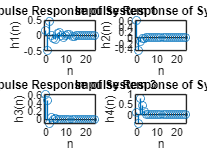

% Impulse Response Calculation and Visualization

% ----------------------------------------------
% This script defines the numerator and denominator coefficients for four systems. 
% It performs partial fraction expansion using the residue function to find the
% residues, poles, and direct terms. Then, it calculates the impulse responses 
% for each system and plots them in a 2x2 subplot layout.

% Define the numerator and denominator coefficients
a1 = [1 0.13 0.52 0.3];
b1 = [0.16 -0.48 0.48 -0.16];

a2 = [1 -0.268];
b2 = [0.634 -0.634];

a3 = [1 0.268];
b3 = [0.634 0.634];

a4 = [10 -5 1];
b4 = [1 -5 10];

% Use the residue function to perform partial fraction expansion
[r, p, k] = residue(b1, a1);
[r2, p2, k2] = residue(b2, a2);
[r3, p3, k3] = residue(b3, a3);
[r4, p4, k4] = residue(b4, a4);

% Determine the impulse responses
n = 0:24;
h1 = zeros(1, length(n));
h2 = zeros(1, length(n));
h3 = zeros(1, length(n));
h4 = zeros(1, length(n));

for i = 1:length(p)
h1 = h1 + r(i)*p(i).^n;
end
h1 = [k h1(1:24)];

for i = 1:length(p2)
h2 = h2 + r2(i)*p2(i).^n;
end
h2 = [k2 h2(1:24)];

for i = 1:length(p3)
h3 = h3 + r3(i)*p3(i).^n;
end
h3 = [k3 h3(1:24)];

for i = 1:length(p4)
h4 = h4 + r4(i)*p4(i).^n;
end
h4 = [k4 h4(1:24)];

% Plot the impulse responses
figure;

subplot(2, 2, 1)
stem(n, h1);
xlabel('n');
ylabel('h1(n)');
title('Impulse Response of System 1');

subplot(2, 2, 2)
stem(n, h2);
xlabel('n');
ylabel('h2(n)');
title('Impulse Response of System 2');

subplot(2, 2, 3)
stem(n, h3);
xlabel('n');
ylabel('h3(n)');
title('Impulse Response of System 3');

subplot(2, 2, 4)
stem(n, h4);
xlabel('n');
ylabel('h4(n)');
title('Impulse Response of System 4');


% Impulse Response Calculation and Visualization Using Filter
% -----------------------------------------------------------
% This script defines the numerator and denominator coefficients for four systems.
% It calculates the impulse responses using the filter function and plots them
% in a 2x2 subplot layout.

% Define the numerator and denominator coefficients for System 1
a1 = [1 0.13 0.52 0.3];
b1 = [0.16 -0.48 0.48 -0.16];

% Define the numerator and denominator coefficients for System 2
a2 = [1 -0.268];
b2 = [0.634 -0.634];

% Define the numerator and denominator coefficients for System 3
a3 = [1 0.268];
b3 = [0.634 0.634];

% Define the numerator and denominator coefficients for System 4
a4 = [10 -5 1];
b4 = [1 -5 10];

% Define the time vector and input signal
n = 0:24;   % Time vector
N = 25;     % Length of the signal
x = [1 zeros(1, N-1)];   % Impulse signal

% Calculate the impulse response for System 1
h1 = filter(b1, a1, x);

% Calculate the impulse response for System 2
h2 = filter(b2, a2, x);

% Calculate the impulse response for System 3
h3 = filter(b3, a3, x);

% Calculate the impulse response for System 4
h4 = filter(b4, a4, x);

% Plot the impulse responses for each system
figure;

% Plot for System 1
subplot(2, 2, 1)
stem(n, h1)
xlabel('n');             % Label x-axis
ylabel('h1(n)');         % Label y-axis
title('Impulse Response of System 1');  % Title for the subplot

% Plot for System 2
subplot(2, 2, 2)
stem(n, h2)
xlabel('n');             % Label x-axis
ylabel('h2(n)');         % Label y-axis
title('Impulse Response of System 2');  % Title for the subplot

% Plot for System 3
subplot(2, 2, 3)
stem(n, h3)
xlabel('n');             % Label x-axis
ylabel('h3(n)');         % Label y-axis
title('Impulse Response of System 3');  % Title for the subplot

% Plot for System 4
subplot(2, 2, 4)
stem(n, h4)
xlabel('n');             % Label x-axis
ylabel('h4(n)');         % Label y-axis
title('Impulse Response of System 4');  % Title for the subplot

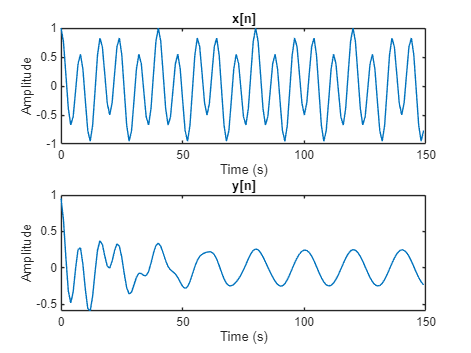

% Sinusoidal Signal Processing with Notch Filter
% ----------------------------------------------
% This script creates a time index and generates a signal `x` as the sum of two
% sinusoids. It then defines and applies a notch filter to the signal `x` to
% create a filtered signal `y`. Finally, it plots the original signal `x` and
% the filtered signal `y` for comparison.

% Define the time index
n = 0:149;

% Generate the sum of two sinusoids
x = 0.25*cos((pi*n)/10) + 0.75*cos((pi*n)/4);

% Define the notch filter coefficients
b = 0.9543 .* [1 -2*cos(pi/4) 1];
a = [1 -1.9*cos(pi/4) 0.9025];

% Apply the notch filter to the signal x[n]
y = filter(b, a, x);

% Plot the original and filtered signals
figure;

% Plot the original signal x[n]
subplot(2, 1, 1);
plot(n, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('x[n]');

% Plot the filtered signal y[n]
subplot(2, 1, 2);
plot(n, y);
xlabel('Time (s)');
ylabel('Amplitude');
title('y[n]');

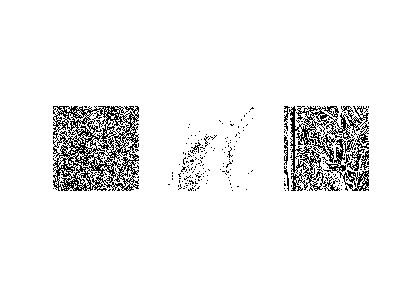

% Image Filtering with Different Kernels
% --------------------------------------
% This script defines three different filter kernels and applies each to an image.
% The filtered images are displayed side by side for comparison.

% Define the filter kernels
h1 = [-1 -1 -1; -1 8 -1; -1 -1 -1];
h2 = [-1 -1 -1; -1 9 -1; -1 -1 -1];
h3 = [0 1 2; -1 0 1; -2 -1 0];

% Convert rgb image to greyscale
A = rgb2gray(imread("lena_color.tiff", "tiff"));


% Apply the first filter and display the result
subplot(1, 3, 1)
y = filter2(h1, A, 'same');
imshow(y);

% Apply the second filter and display the result
subplot(1, 3, 2)
y = filter2(h2, A, 'same');
imshow(y);

% Apply the third filter and display the result
subplot(1, 3, 3)
y = filter2(h3, A, 'same');
imshow(y);